## Heparosan Polydispersion Index and Molecular Weight Estimation 

Base on data from Chavaroche, Anaïs AE, et al. "Synthesis of heparosan oligosaccharides by Pasteurella multocida PmHS2 single-action transferases." *Applied microbiology and biotechnology* 95.5 (2012): 1199-1210.

Introduce the actual concentrations of precursos in the variables (posible concentrations between 0.25mM and 5mM):

`GlcNAc_actual_concentration = 1; %mM`

`GlcUA_actual_concentration = 0.5; %mM`

To obtain the estimated polydispesion index of the produced Heparosan in the variable `PDI_estimated.`

Note: this is for a concentraton of the PmHS2 enzyme of around 55-60 µg/ml. 

load CM50.mat
%clear all
GlcNAc = [0.25, 5]

GlcNAc =     0.2500    5.0000


GlcUA= [0.25, 5]

GlcUA =     0.2500    5.0000


% Generate a grid of all combinations of GlcNAc and GlcUA
[GlcNAc_grid, GlcUA_grid] = ndgrid(GlcNAc, GlcUA);

% Reshape the output into a matrix where each row is a combination of GlcNAc and GlcUA
X = [GlcNAc_grid(:), GlcUA_grid(:)]; % Where NAc is the first dimension and UA the second.

PDI = [1.17 1.25; 1.22 1.63]'

PDI =     1.1700    1.2200
    1.2500    1.6300


Z_pdi = PDI(:)

Z_pdi =     1.1700
    1.2500
    1.2200
    1.6300



Hep_Mw = [135 25; 55 65]'

Hep_Mw =    135    55
    25    65


Z_Mw = Hep_Mw(:)

Z_Mw =    135
    25
    55
    65


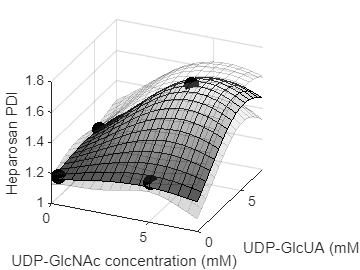

[X Z_pdi Z_Mw];

rng default
gprMdl_pdi = fitrgp(X, Z_pdi,'Basis','constant','Beta',1.07,'FitMethod','none',...
'PredictMethod','exact','KernelFunction','squaredexponential',...
'KernelParameters',[3.8;0.1],'Sigma',0.01);

% Predict new data
% Generate a grid of GlcNAc and GlcUA values
[GlcNAc_I, GlcUA_I] = meshgrid(0:0.5:10, 0:0.5:10);

% Predict PDI values using the Gaussian Process Regression Model
[PDI_pred,PDI_sd,PDI_int] = predict(gprMdl_pdi, [GlcNAc_I(:), GlcUA_I(:)]);

%Mw_pred = predict(gprMdl_Mw, [GlcNAc_I(:), GlcUA_I(:)]);

% Reshape the predicted PDI values into the same size as the grid
PDI_predr = reshape(PDI_pred, size(GlcNAc_I));
PDI_int_u = reshape(PDI_int(:,1), size(GlcNAc_I));
PDI_int_l = reshape(PDI_int(:,2), size(GlcNAc_I));


%Mw_predr = reshape(Mw_pred, size(GlcNAc_I));
clf
% Plot the surface of GlcNAc, GlcUA, and PDI
figure
colormap("gray")
surf(GlcNAc_I, GlcUA_I, PDI_predr)
hold on
plot3(X(:,1),X(:,2), Z_pdi,'MarkerFaceColor',[0 0 0],'MarkerEdgeColor',[0 0 0],...
    'MarkerSize',30,...
    'Marker','.',...
    'LineStyle','none',...
    'Color',[0 0 0]);

surf(GlcNAc_I, GlcUA_I, PDI_int_l,'FaceAlpha',0.2,'EdgeAlpha',0.2)
surf(GlcNAc_I, GlcUA_I, PDI_int_u,'FaceAlpha',0.2,'EdgeAlpha',0.2)
xlabel('UDP-GlcNAc concentration (mM)')
zlabel('Heparosan PDI')
ylabel('UDP-GlcUA (mM)')

view([74 34])
% Uncomment the following line to preserve the X-limits of the axes
xlim([0 7.5]);
% Uncomment the following line to preserve the Y-limits of the axes
ylim([0 7.5]);
% Uncomment the following line to preserve the Z-limits of the axes
zlim([1 1.8]);
view([24 29]);

% Fit gausian process for the molecular weight


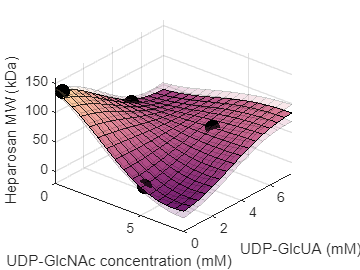



rng default
% gprMdl_Mw = fitrgp(X, Z_Mw,'Basis','constant','Beta',72,'FitMethod','none',...
% 'PredictMethod','exact','KernelFunction','squaredexponential',...
% 'KernelParameters',[3.8;40],'Sigma',1.5);

  gprMdl_Mw = fitrgp(X, Z_Mw,'Basis','constant','Beta',72,'FitMethod','none',...
 'PredictMethod','exact','KernelFunction','squaredexponential',...
 'KernelParameters',[3.8;10],'Sigma',1.5);

% Predict PDI values using the Gaussian Process Regression Model
% Int is the 95 percent confidence interval
[Mw_pred,Mw_sd,Mw_int] = predict(gprMdl_Mw, [GlcNAc_I(:), GlcUA_I(:)]);

% Reshape the predicted PDI values into the same size as the grid
Mw_predr = reshape(Mw_pred, size(GlcNAc_I));
Mw_int_u = reshape(Mw_int(:,1), size(GlcNAc_I));
Mw_int_l = reshape(Mw_int(:,2), size(GlcNAc_I));


%Mw_predr = reshape(Mw_pred, size(GlcNAc_I));
clf
figure
colormap(Colormap_MW50);
% Plot the surface of GlcNAc, GlcUA, and PDI
surf(GlcNAc_I, GlcUA_I, Mw_predr);
hold on
plot3(X(:,1),X(:,2), Z_Mw,'MarkerFaceColor',[0 0 0],'MarkerEdgeColor',[0 0 0],...
    'MarkerSize',30,...
    'Marker','.',...
    'LineStyle','none',...
    'Color',[0 0 0]);

surf(GlcNAc_I, GlcUA_I, Mw_int_l,'FaceAlpha',0.2,'EdgeAlpha',0.2);
surf(GlcNAc_I, GlcUA_I, Mw_int_u,'FaceAlpha',0.2,'EdgeAlpha',0.2);
xlabel('UDP-GlcNAc concentration (mM)')
zlabel('Heparosan MW (kDa)')
ylabel('UDP-GlcUA (mM)')

view([74 34])
% Uncomment the following line to preserve the X-limits of the axes
xlim([0 7.5]);
% Uncomment the following line to preserve the Y-limits of the axes
ylim([0 7.5]);
% Uncomment the following line to preserve the Z-limits of the axes
zlim([-20 160]);
view([39.9866342648846 35.4871815696994]);

% Set the remaining axes properties
%set(axes1,'CLim',[0 140]);
clf
figure
err_shad = Mw_predr(2,:)- [Mw_int_u(2,:)]

err_shad =     4.3427    4.2520    4.8324    5.5943    6.1996    6.4838    6.3875    5.9299    5.2168    4.4898    4.1867    4.7279    6.0406    7.7626    9.6165   11.4362   13.1220   14.6159   15.8890   16.9351   17.7647


shadedErrorBar(GlcNAc_I(2,:),Mw_predr(2,:),err_shad,{'-','Color',[0.865922966637838	0.507691960740146	0.590137121884960],'markerfacecolor',[0.865922966637838	0.507691960740146	0.590137121884960]},1)

Unrecognized function or variable 'shadedErrorBar'.

xlim([0 8 ...
    ])
ylim([-20 150])
grid on
xlabel('UDP-GlcNAc concentration (mM)')
ylabel('Heparosan MW (kDa)')
hold on
plot(GlcNAc,Hep_Mw(:,1).*[0.98; 1.051],'o','MarkerFaceColor',[0 0 0],'MarkerSize',10)